# Assignment 1 - Multi-Modal Sensor Systems (ENG09022) 

#### Author: James O'Connor

#### Student ID: S00214588

## Part 2 - Sensor Networks

The motivation for part one of this assessment is to use Least Squares (LS) and Weighted Least Squares (WLS) estimates to approximate target location.  

Steps are as follows: 

- Create a time-of-arrival (TOA) network with 8 sensors and a single target

- Simulate a measurement at t=1 

- Estimate the location of the target using LS and WLS 

- Compute the Cramer-Rao Lower Bound (CLRB)

% Initialise defaults 
set(gcf,'position',[0,0,800,600])


% Initialise sensor variables 
% (sensors (M), target(N), sensor_locations(th), target_location(x0))
num_sensors=4;
num_target=1;
sensor_locations_1 = [1.2 1.5 1.1 -0.5 -0.9 0.9 -1.4 -1.3];
sensor_locations_2 = [2 2 2 -2 -2 -2 -2 2];
sensor_locations_3 = [3 0.5 1 0.5 -1 0.5 -3 0.5];

target_location =[0.5 0.5];

% Create covariance matrix
cov_matrix = diag(rand(4,1))*0.3

cov_matrix =     0.2522         0         0         0
         0    0.0763         0         0
         0         0    0.2443         0
         0         0         0    0.0731


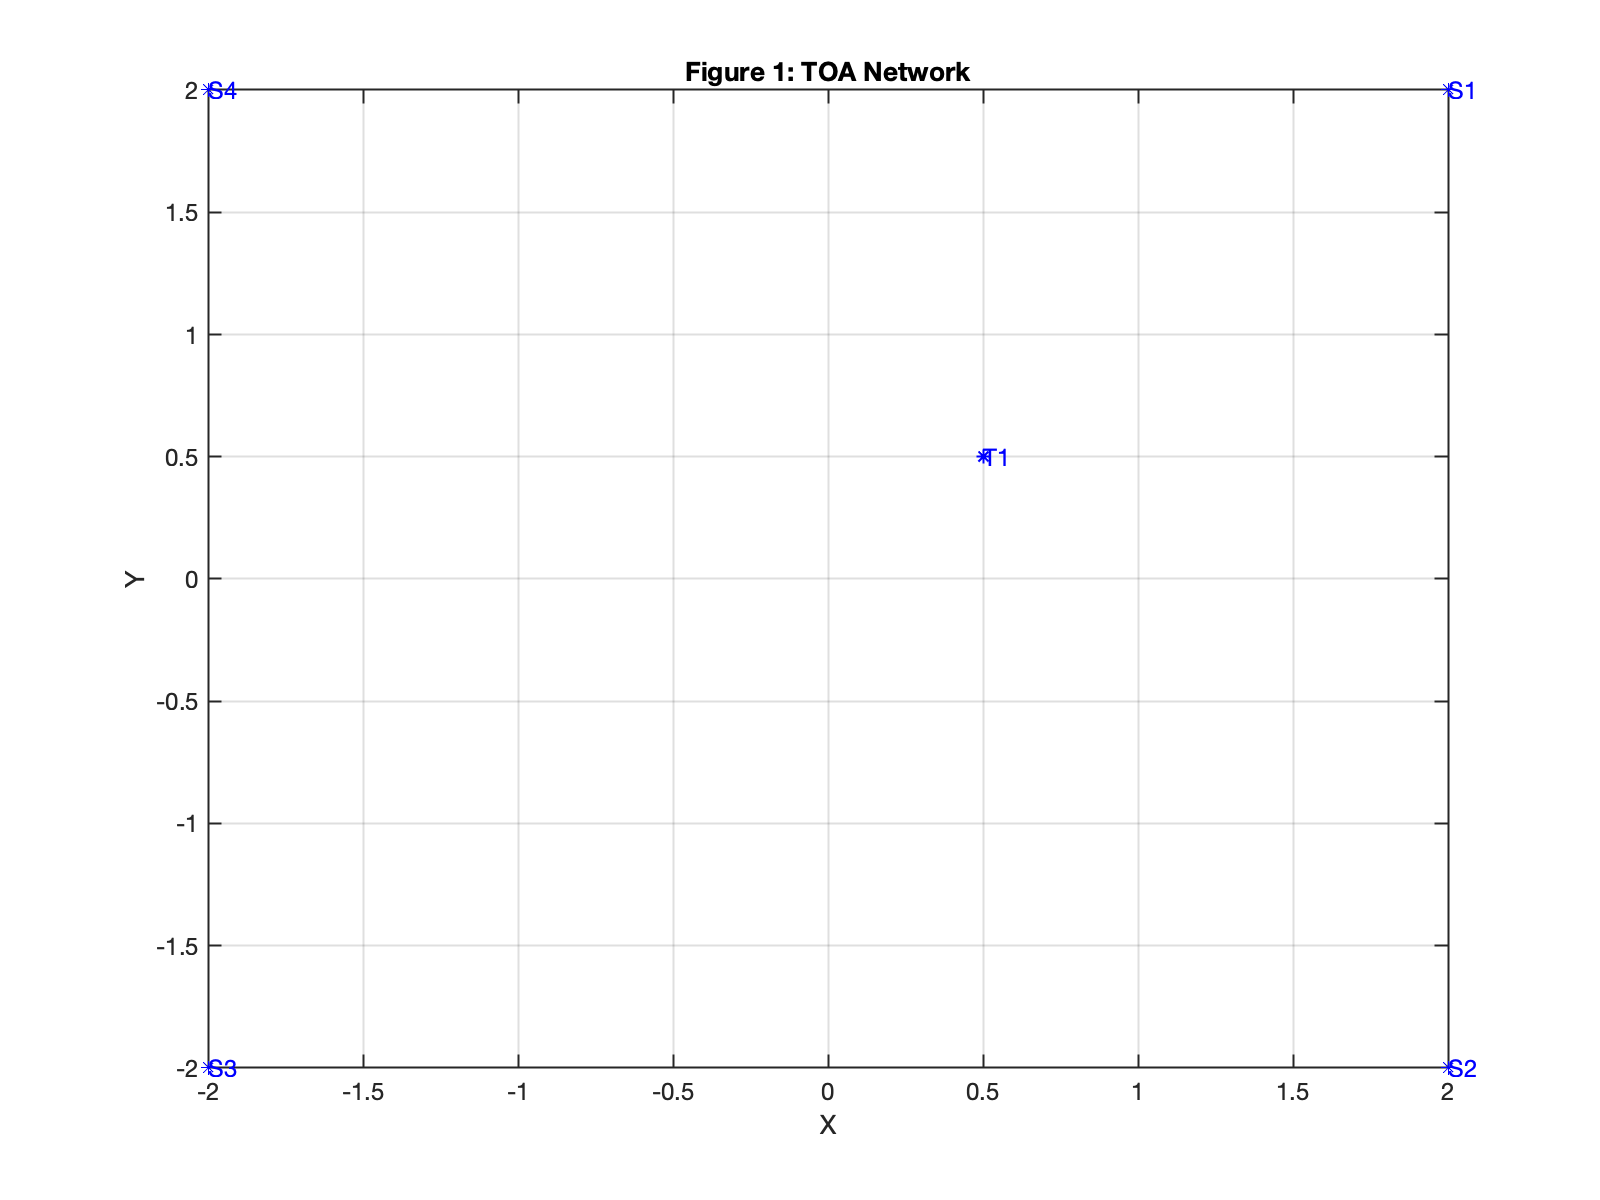


% Create Time of Arrival (TOA) sensor
time_of_arrival_sensor=exsensor('TOA', num_sensors, num_target);
mss1=exmotion('ctcv2d');


% Udpate sensor with defined variables
time_of_arrival_sensor.x0 = target_location;
time_of_arrival_sensor.th = sensor_locations_2;
time_of_arrival_sensor.pe = cov_matrix;

mms = addsensor(mss1,time_of_arrival_sensor);     %  Several sensors can be added sequentially

mms.th = [1,1,1,-1,-1,-1,-1,1]';
mms.x0 = [0.5,0.5,0.5,0.5, 0.5];
mms.pv = diag([1 1 1 1 1]);
mms.pv = 0.4*mms.pv; 	%reduce the velocity
mms.px0 = 12*mms.pv;
y_new = simulate(mms, 5);


% Plot the data                            
plot(time_of_arrival_sensor)
hold on 
grid on
axis([-2 2 -2 2])
title('Figure 1: TOA Network')
xlabel('X')
ylabel('Y')
hold off

## Simulate a measurement at Time(T)=1

y = simulate(time_of_arrival_sensor, 10);
% Analyse our estimate outputs at t=1
% These values are the estimated distance from the respective sensors to the
% target
y.y

ans =     1.9623    3.0163    3.7328    2.6185



% Create a least squares estimate
xls=ls(time_of_arrival_sensor,y_new);
xls.y

ans =     2.1213    2.9155    3.5355    2.9155
    2.1213    2.9155    3.5355    2.9155
    2.1213    2.9155    3.5355    2.9155
    2.1213    2.9155    3.5355    2.9155
    2.1213    2.9155    3.5355    2.9155
    2.1213    2.9155    3.5355    2.9155
    2.1213    2.9155    3.5355    2.9155
    2.1213    2.9155    3.5355    2.9155
    2.1213    2.9155    3.5355    2.9155
    2.1213    2.9155    3.5355    2.9155



% Create weighted least squares estimates
xwls=wls(time_of_arrival_sensor,y_new);
xwls.y

ans =     2.7962    3.1227    2.8607    2.3809
    2.1581    2.8943    3.4987    2.9188
    1.9967    3.1240    3.6602    2.7674
    0.9350    3.0084    4.7218    3.3980
    0.5592    3.2969    5.0976    3.2918
    0.8981    3.6009    4.7587    2.8233
   -0.8231    4.4244    6.4800    2.8348
   -0.6237    4.6146    6.2805    2.5479
   -0.2499    4.3054    5.9067    2.6757
    0.7227    4.0305    4.9341    2.4789


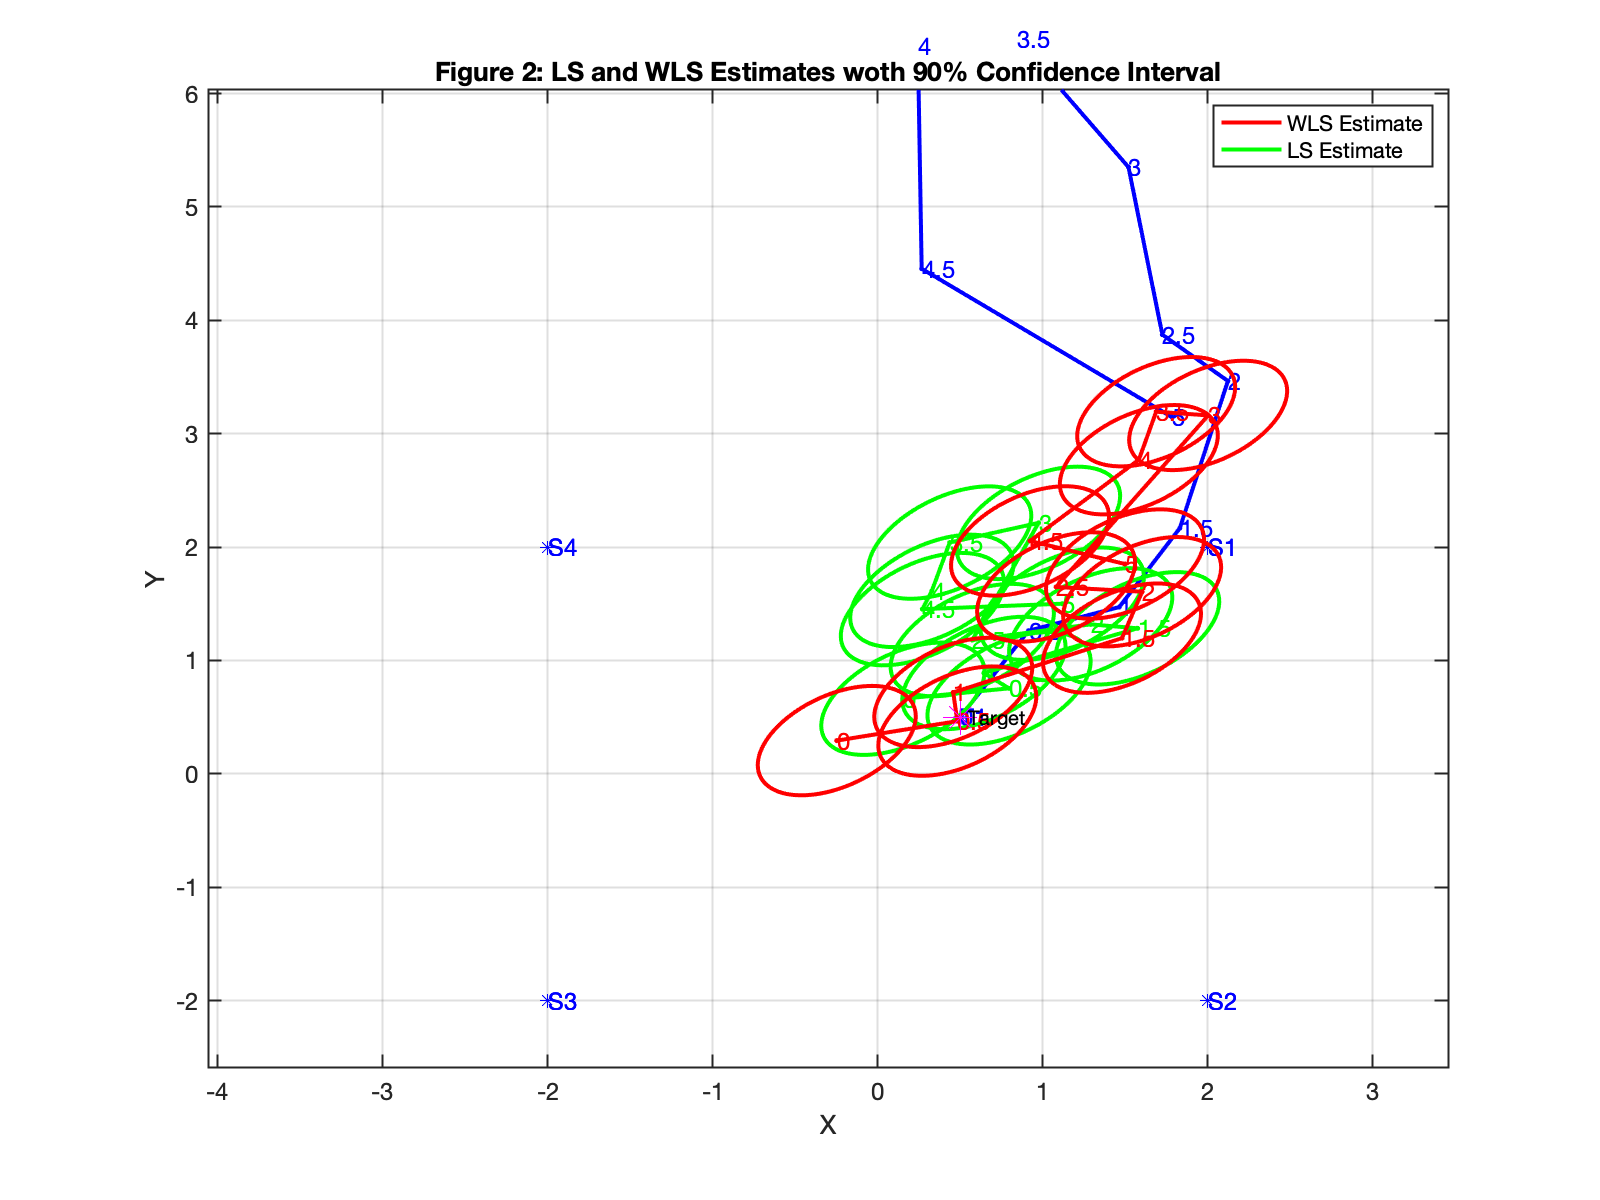


% Plot Data
plot(time_of_arrival_sensor)
hold on 
xplot2(y_new,xls,xwls,'conf',80,'linewidth', 2) %plots the 90% CI for both estimators
hold on
plot(target_location(1), target_location(2), 'm*', 'markersize',15);
text(target_location(1)+0.05, target_location(2),'Target');
hold on
grid on
title('Figure 2: LS and WLS Estimates woth 90% Confidence Interval');
xlabel('X');
ylabel('Y');
f=get(gca,'Children');
legend([f(4),f(31)],'WLS Estimate','LS Estimate');
xlim([-5 5])
ylim([-5 5])
hold off

## Add Cramer-Rao Lower Bound (CLRB)

The CLRB gives a lower bound for the variance of an unbiased estimator

crlb(y_new);2

Check for missing argument or incorrect argument data type in call to function 'crlb'.


% Plot the data                            
plot(time_of_arrival_sensor)
hold on 
grid on
axis([-2 2 -2 2])
title('Figure 1: TOA Network')
xlabel('X-Axis')
ylabel('Y-Axis')
f=get(gca,'Children');
legend([f(20)],'CLRB');
hold off

## Discussion of Results 

We have successfully created LS and WLS estimators and plotted them against each other with their respective 90% confidence intervals. 

From running the simulation t=1 many times, it was clear that the WLS estimator performed better than the LS estimator in terms of accuracy and degree of confidence. 

This makes sense intuitively, as our y sensor estimates get weighted inversely proportional to the distance to the target. 